Compare the difference between potential maximum growth rate and the observed rate

Uses data from pipeline3 (dat3_[fixed|variable]initenzyme.mat)

Initialize Cobra Toolbox before executing

%Build data for the max potential rate
overwritefiles = true;
args.p3.variableInitEnzyme = true;
args.p3.variableInitEnzyme = false;
args.p3.v.initenzyme = args.p3.v.initialpop * 10^-3.5;
args.p3.v.enzInMaint = false;
args.p3.v.addEnzymeToMaint = false;
alphas = -(.25:.25:10);
alphas = 10.^alphas;
v = args.p3.v;
model_default = load('C:\sync\biomes\models\yeastGEM_8.3.2.mat');
model_default = model_default.model;
%remove non-media uptakes
model = model_default;
model.mets{311} = 'nh4[e]';
model.mets{345} = 'co2[e]';
model.mets{431} = 'glc-D[e]';
model.mets{512} = 'ergst[e]';
model.mets{572} = 'gthox[e]';
model.mets{603} = 'h+[e]';
model.mets{612} = 'h2o[e]';
model.mets{720} = 'fe2[e]';
model.mets{1005} = 'o2[e]';
model.mets{1037} = 'pi[e]';
model.mets{1055} = 'k[e]';
model.mets{1135} = 'so4[e]';
model.mets{1215} = 'zymst[e]';
baselb = model_default.lb;
allexchange = findExchRxns(model) & (model.lb < 0);
allexchange = find(allexchange);
model.lb(allexchange) = 0;
model.lb(3415) = baselb(3415); %maintenance
media = {'zymst[e]' 'ergst[e]' 'o2[e]' 'h2o[e]' 'co2[e]' 'pi[e]' ...
    'so4[e]' 'nh4[e]' 'k[e]' 'fe2[e]' 'glc-D[e]' 'gthox[e]' 'h+[e]'};
for i = 1:length(media)
    idx = stridx(media{i},model.mets,false);
    col = model_default.S(idx,:);
    ex = intersect(allexchange,find(col));
    model.lb(ex) = baselb(ex);
end

mu = zeros(length(alphas),1);

for i = 1:length(alphas)
    v.alpha = alphas(i);
    enzmodel = prepareYeastGEMModel('model',model,'alpha',v.alpha,'vmax_glc',v.vmax_glc,'maintRxnAsObjective',false,'atp',v.atp_per_peptide,'gtp',v.gtp_per_peptide,'addEnzymeToMaint',v.enzInMaint);
    %enzmodel.lb(stridx('D-glucose exchange' ,model.rxnNames)) = -1;
    enzmodel.lb(stridx('glutathione disulfide exchange',model.rxnNames)) = 0;
    opt = optimizeCbModel(enzmodel);
    mu(i) = opt.f;
end

dat3.mu = cellfun(@(x,y) x./y(1:end-1),dat3.biomass_delta,dat3.biomass,'uniformoutput',false);
dat3.maxrate = cellfun(@(x) max(x),dat3.mu);

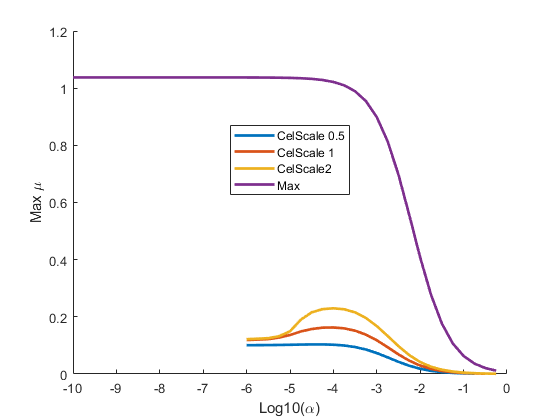

%data for celscales
f = figure();
hold on;
d = dat3(dat3.celscale==.5,:);
plot(log10(d.alpha),d.maxrate,'linewidth',2);
d = dat3(dat3.celscale==1,:);
plot(log10(d.alpha),d.maxrate,'linewidth',2);
d = dat3(dat3.celscale==2,:);
plot(log10(d.alpha),d.maxrate,'linewidth',2);
plot(log10(alphas),mu,'linewidth',2);
legend({'CelScale 0.5' 'CelScale 1' 'CelScale2' 'Max'},'location','best');
xlabel('Log10(\alpha)');
ylabel('Max \mu');

%save the figure
if overwritefiles
    savefig(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\growthrate_ObservedVsMax.fig','compact');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\growthrate_ObservedVsMax.png');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\growthrate_ObservedVsMax.eps');%for LaTeX
end

Observe the glucose buildup for range of Alphas

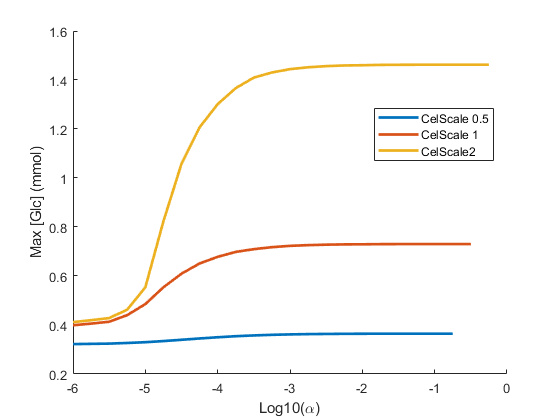

d = dat3(dat3.celscale==.5,:);
figure();
hold on;
d = dat3(dat3.celscale==.5,:);
gmax = cellfun(@(x) max(x),d.glc_amt);
plot(log10(d.alpha),gmax,'linewidth',2);
d = dat3(dat3.celscale==1,:);
gmax = cellfun(@(x) max(x),d.glc_amt);
plot(log10(d.alpha),gmax,'linewidth',2);
d = dat3(dat3.celscale==2,:);
gmax = cellfun(@(x) max(x),d.glc_amt);
plot(log10(d.alpha),gmax,'linewidth',2);
legend({'CelScale 0.5' 'CelScale 1' 'CelScale2'},'location','best');
hold off;
xlabel('Log10(\alpha)');
ylabel('Max [Glc] (mmol)');